# Template of Manipulator Short project: Skull tumor surgery

clc;
clear;
close all

## The Robotic environment (10%)

Use: 'c = uisetcolor' to chose color

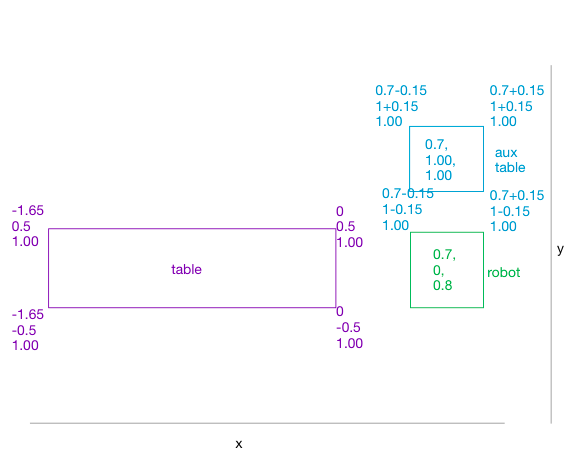

### Operating table

 It can be raised, lowered, and tilted in any direction, and an auxiliary table for the tools. Define: vertices and Faces and use  'patch'  functions to model it.

hold on
Transformations.T_U_TB  = transl(-1.65,-0.5,1.00)*troty(deg2rad(-10));
trplot(Transformations.T_U_TB, 'frame', 'T_U_TB', 'color', '#fc814a', 'length', 0.3, 'text_opts', {'FontSize', 7});
print_operating_table(Transformations.T_U_TB)

### Auxiliar table

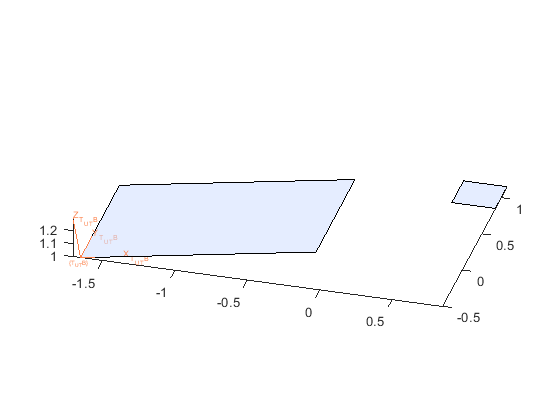

Transformations.T_U_AT = transl(0.55, 0.85, 1.00);
print_auxiliary_table(Transformations.T_U_AT)

### Human skull model

Embedded in the head of the human.

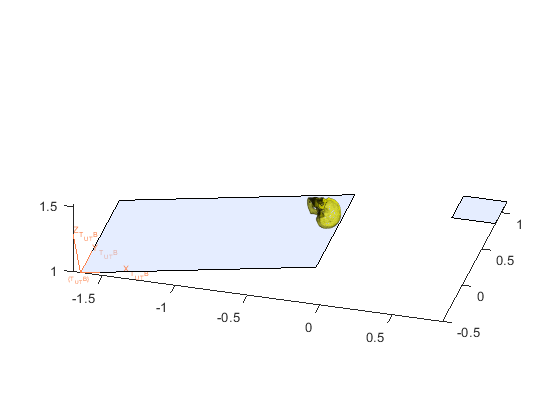

print_skull(Transformations.T_U_TB)

### 3D model of a human body 

Situate the human model on the operating table

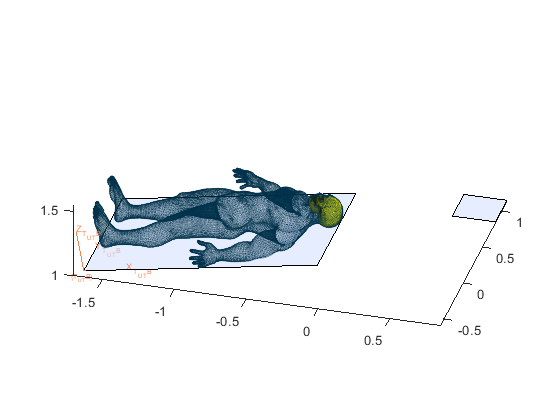

print_human_body(Transformations.T_U_TB)

### Dicom image vs Image reference frame

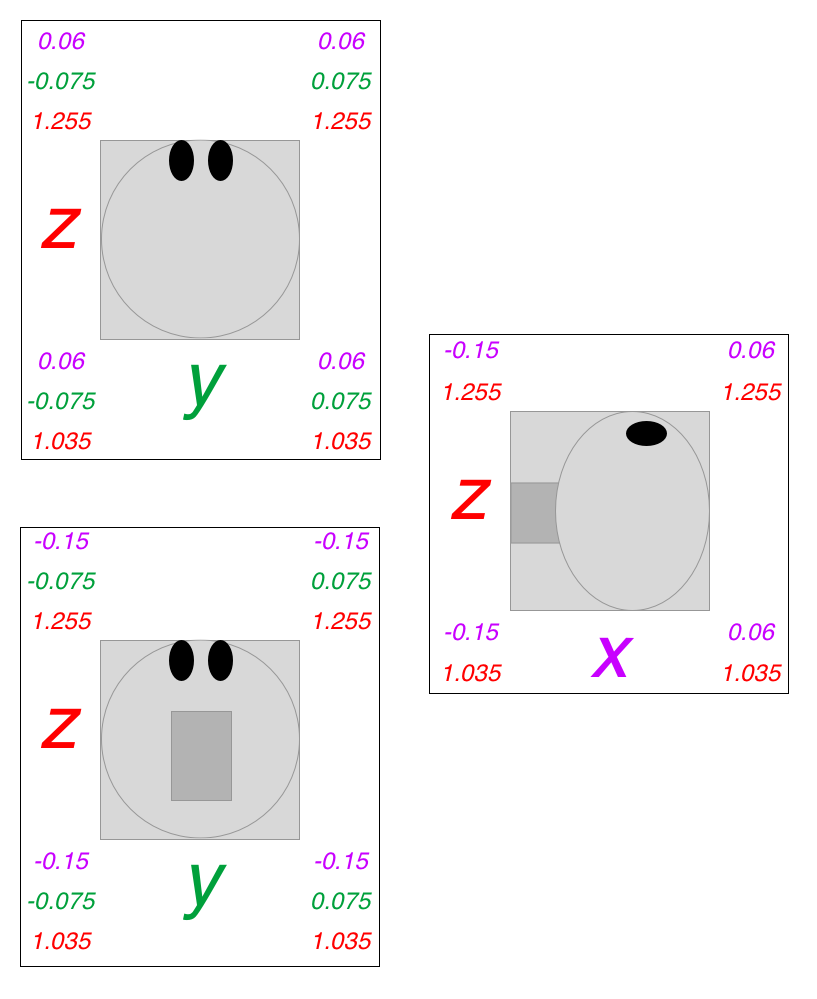

min:

- x = -0.15

- y = -0.075

- z = 1.035

max:

- x = 0.06

- y = 0.075

- z = 1.255

b_min = [-0.15 -0.075 1.035];
b_max = [ 0.06  0.075 1.255];

BOX.anchura = b_max(2)-b_min(2);
BOX.fondo = b_max(3)-b_min(3);
BOX.altura = b_max(1)-b_min(1);

Go to ---- /MatlabDrive/Robotica_20_21_2Q/2_Rotations\3_Rotating_about_axis.mlx and use the Box as a container of the skull. You can infer the Image Reference Frame {I}

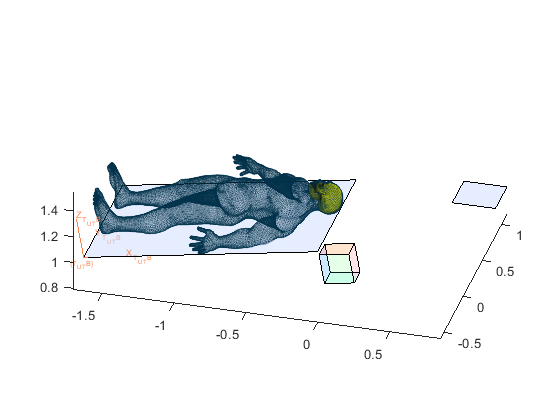

BOX.desired_pos = [1.65-0.15 0.5-0.075 1-1.255]; % T_TB_BOX
BOX.t_desired_pos = transl(1.65-0.15, 0.5-0.075, 1-1.255); % T_TB_BOX
BOX.rotations = roty(-pi/2)*rotx(pi/2);
BOX.trotations = trotz(-pi/2)*trotx(-pi/2);
Transformations.T_U_BOX = transform_point(BOX.rotations+BOX.desired_pos,Transformations.T_U_TB);
print_box(Transformations.T_U_TB,BOX);

trplot(Transformations.T_U_BOX,  'frame', 'T_U_BOX',  'color', '#791e94', 'length', 0.3, 'text_opts', {'FontSize', 7});

Error using trplot (line 137)
trplot operates only on transform (4x4) or rotation matrix (3x3)

### Fiducials

Use the Dicom images to register the fiducial relative to Image Reference Frame {I}.

Think about how many reference frames are envolved.

Fiducial 1:

- Image = 32

- x = 70

- y = 213.4

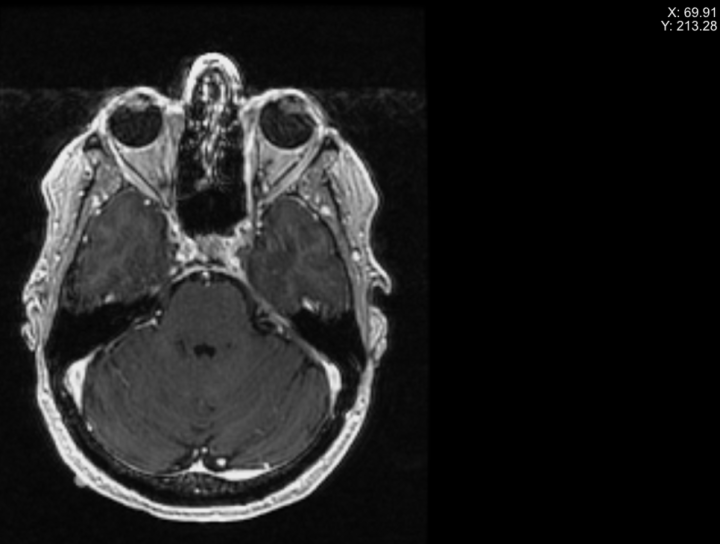

Fiducial 2:

- Image = 65

- x = 185.8

- y = 210.3

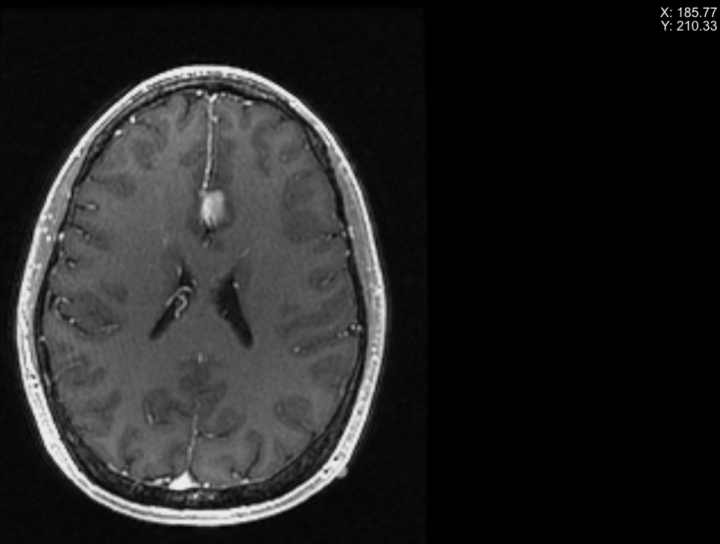

Fiducial 3:

- Image = 94

- x = 121.45

- y = 61.65

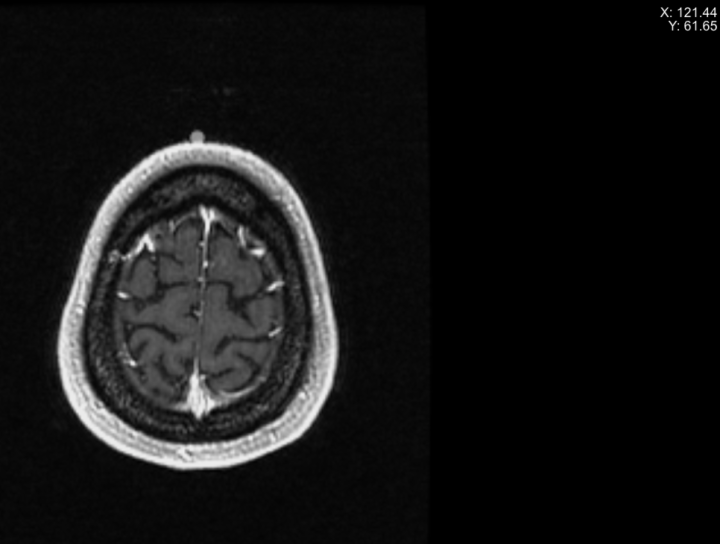

Max and min in dico images:

To calculate these points into an IRF, we must define a min and max point of reference so we can translate the points to another IRF. The max and min point will be defined by the maximum edges of the head on its wider image (55).

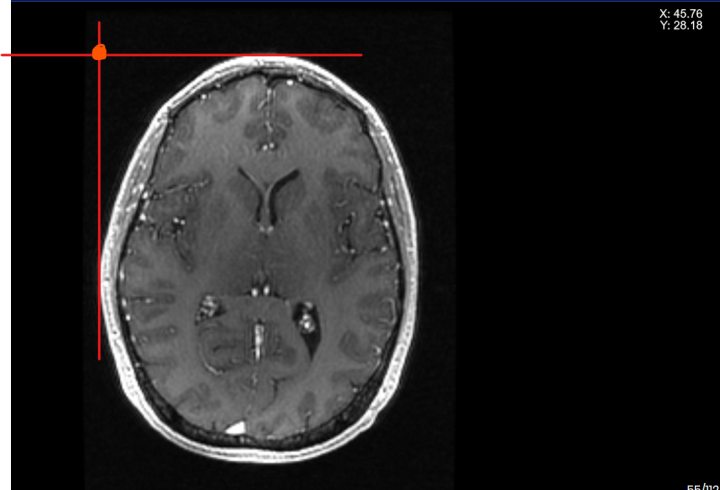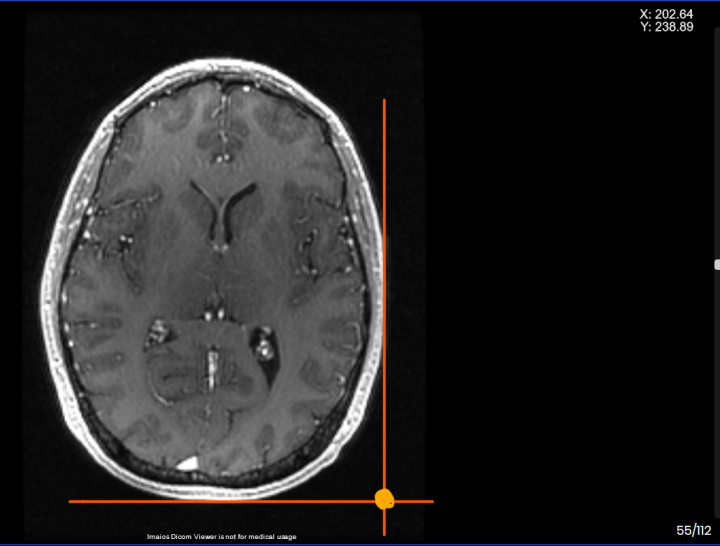

Min: *(defined in function get_point_from_dicom at the end of this document)*

- d_min.x = 45.76;

- d_min.y = 28.18;

- d_min.z = 1;

Max: *(defined in function get_point_from_dicom at the end of this document)*

- d_max.x = 202.64;

- d_max.y = 238.89;

- d_max.z = 112;

### Fiducial 1

d_f1 = [ 70 213.4 32 ];
f1 = get_proportion_point_from_dicom(d_f1);
b_f1 = get_box_coords_of_prop_point(f1, BOX);
print_fiducial(b_f1)

### Fiducial 2

d_f2 = [ 185.8 210.3 65 ];
f2 = get_proportion_point_from_dicom(d_f2);
b_f2 = get_box_coords_of_prop_point(f2, BOX);
print_fiducial(b_f2)

### Fiducial 3

d_f3 = [ 121.45 61.65 94];
f3 = get_proportion_point_from_dicom(d_f3);
b_f3 = get_box_coords_of_prop_point(f3, BOX);
print_fiducial(b_f3)

### Tumor points

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

#### Layers: from dicom image 65 to dicom image 89

We take the upper and lowest point for every 5 layers in order to calculate the mid point and its radius.

65

- x = 130.76 

- y1 = 85.62

- y2 = 100.6 

layers(1).z = 65;
layers(1).x = 130.76;
layers(1).y1 = 85.62;
layers(1).y2 = 100.6;

70

- x = 131.75 

- y1 = 82.66 

- y2 = 112.20 

layers(2).z = 70;
layers(2).x = 131.75;
layers(2).y1 = 82.66;
layers(2).y2 = 112.20;

75

- x = 132.8 

- y1 = 80.69

- y2 = 115.81 

layers(3).z = 75;
layers(3).x = 132.8;
layers(3).y1 = 80.69;
layers(3).y2 = 115.81;

80

- x = 133.6  

- y1 = 80.69 

- y2 = 114.17  

layers(4).z = 80;
layers(4).x = 133.6; 
layers(4).y1 = 80.69;
layers(4).y2 = 114.17;

85

- x = 132.40 

- y1 = 87.59

- y2 = 108.59

layers(5).z = 85;
layers(5).x = 132.40;
layers(5).y1 = 87.59;
layers(5).y2 = 108.59;

89

- x = 131.9 

- y1 = 93.49 

- y2 = 103.67

layers(6).z = 89;
layers(6).x = 131.9;
layers(6).y1 = 93.49;
layers(6).y2 = 103.67;


Now, let's calculate the circle points:

[circles_points circle] = calculate_circles_details(layers, BOX);
print_tumor(circles_points)

## *First approach (10%)  *

*Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

### Robot manipulator

Consider  the best position of manipulator to be nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

Use: p560.base & p560.tool to locate the Puma and add the tool.

mdl_puma560
p560.base = [0.7 0 0.8];
p560.tool = [0 0 0.2];
T_U_EE = Transformations.T_U_BOX*transl(-BOX.anchura/2,BOX.fondo/2,BOX.altura)*troty(pi);
Q = p560.ikine(T_U_EE);
reset_workspace(Transformations,BOX)
% p560.plot(Q) %lo plotearemos más tarde
xlim([-1.01 0.89]);
ylim([-0.59 1.15]);
zlim([0.36 2.03]);
view([148.95 33.31]);

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {Tt} Table_tool

- {EE} End Efector

RF_U    = transl(0,0,0);
T_U_R   = transl(p560.base.t(1), p560.base.t(2), p560.base.t(3));
Transformations.T_U_BOX % Box / Image
Transformations.T_U_TB % Table body
Transformations.T_U_AT % Table Tool
T_U_EE; % defined above

reset_workspace(Transformations,BOX)

trplot(RF_U,   'frame', 'RF_U',   'color', '#2c8c99', 'length', 0.3, 'text_opts', {'FontSize', 7});
trplot(T_U_R,  'frame', 'T_U_R',  'color', '#931621', 'length', 0.3, 'text_opts', {'FontSize', 7});
trplot(Transformations.T_U_BOX,  'frame', 'T_U_BOX',  'color', '#791e94', 'length', 0.3, 'text_opts', {'FontSize', 7});
trplot(Transformations.T_U_TB, 'frame', 'T_U_TB', 'color', '#fc814a', 'length', 0.3, 'text_opts', {'FontSize', 7});
trplot(T_U_TT, 'frame', 'T_U_TT', 'color', '#6874e8', 'length', 0.3, 'text_opts', {'FontSize', 7});
trplot(T_U_EE, 'frame', 'T_U_EE', 'color', '#f90093', 'length', 0.3, 'text_opts', {'FontSize', 7});

xlim([-1.68 0.98]); 
ylim([-1.32 1.34]); 
zlim([-0.03 1.64]); 
view([-33.61 34.51]);

### Transformations

Get all transformations

T_R_I  = inv(T_U_R) * T_U_I;
T_R_TB = inv(T_U_R) * T_U_TB;
T_R_TT = inv(T_U_R) * T_U_TT;
T_R_EE = inv(T_U_R) * T_U_EE;

T_I_R  = inv(T_U_I) * T_U_R;
T_I_TB = inv(T_U_I) * T_U_TB;
T_I_TT = inv(T_U_I) * T_U_TT;
T_I_EE = inv(T_U_I) * T_U_EE;

T_TB_R  = inv(T_U_TB) * T_U_R;
T_TB_I  = inv(T_U_TB) * T_U_I;
T_TB_TT = inv(T_U_TB) * T_U_TT;
T_TB_EE = inv(T_U_TB) * T_U_EE;

T_TT_R  = inv(T_U_TT) * T_U_R;
T_TT_I  = inv(T_U_TT) * T_U_I;
T_TT_TB = inv(T_U_TT) * T_U_TB;
T_TT_EE = inv(T_U_TT) * T_U_EE;

T_EE_R  = inv(T_U_EE) * T_U_R;
T_EE_I  = inv(T_U_EE) * T_U_I;
T_EE_TB = inv(T_U_EE) * T_U_TB;
T_EE_TT = inv(T_U_EE) * T_U_TT;

### Tumor points in Robot Frame

circles_points_RF = [];
for i=1:348
    circles_points_RF(:,i) = inv(T_U_R)*[circles_points(:,i); 1];
end

## Surgery (40%)

reset_workspace(Transformations,BOX); 

Define some variables we will be using in the following sections:

tumor_centre_in_dicom = circle(3).center_point; % We take the third circle, since it is one of the 2 most centered ones.
incision_point = calculate_incision_point(tumor_centre_in_dicom, BOX);
safe_zone_point = calculate_safe_zone_point(tumor_centre_in_dicom, BOX);
tumor_point = get_box_coords_of_prop_point(tumor_centre_in_dicom, BOX);

position_ini = transl(incision_point(1),incision_point(2),incision_point(3))*troty(-pi/2);
position_safe = transl(safe_zone_point(1),safe_zone_point(2),safe_zone_point(3))*troty(-pi/2);

t = [0:0.3:2]';

### Biopsy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with the best view.

position_tumor = transl(tumor_point(1),tumor_point(2),tumor_point(3))*troty(-pi/2);

T_going = ctraj(position_ini,position_tumor,length(t));
q_going = p560.ikine(T_going);

T_returning = ctraj(position_tumor,position_ini,length(t));
q_returning = p560.ikine(T_returning);

%camzoom(3);
% p560.plot( ...
%     [q_going; q_returning], ...  
%     'zoom', 4, ...
%     'trail', {'r', 'LineWidth', 1.5}, ...
%     'workspace', [-0.6 1.3 -0.6 1.3 0.5 1.3],...
%     'view', [30 20] ...
% );
xlim = ([-0.6 1.3]); 
ylim = ([-0.6 1.3]);
zlim = ([0.5 1.3]);

### Trepanation

Prepare a script that perform trepanation.

reset_workspace(Tranformations,BOX); 

% going to tool table to change the tool
position_tt = T_U_TT*transl(0.15, 0.15, 0)*trotx(-pi/2);
q_going_change_tool = p560.jtraj(position_ini,position_tt,t);
q_returning_change_tool = p560.jtraj(position_tt,position_safe,t);

% camzoom(2);
% p560.plot( ...
%     [q_going_change_tool; q_returning_change_tool], ...  
%     'zoom', 4, ...
%     'trail', {'r', 'LineWidth', 1.5}, ...
%     'workspace', [-0.6 1.3 -0.6 1.3 0.5 1.3],...
%     'view', [30 20] ...
% );
xlim = ([-0.6 1.3]); 
ylim = ([-0.6 1.3]); 
zlim = ([0.5 1.3]); 

reset_workspace(Transformations,BOX); 

% TREPANATION
tumor_radius = circle(3).radius*BOX.fondo;

% calculo de la rotación
n = 50; % Number of iterations

for i=1:n
 trepanation_pose(:,:,i) = ... 
    position_ini* ... 
    trotz(2*pi*i/n)* ...
    transl(-tumor_radius, 0, 0)* ...
    troty(deg2rad(45)) ...
 ;
end

T_going = ctraj(position_safe,trepanation_pose(:,:,1),length(t));
q_going = p560.ikine(T_going);

% plot de trazado resultante y puntos de referencia
Q = p560.ikine(trepanation_pose, 'run');

T_returning = ctraj(trepanation_pose(:,:,end),position_safe,length(t));
q_returning = p560.ikine(T_returning);

camzoom(3);
% p560.plot( ...
%     [q_going ; Q ; q_returning], ...
%     'trail', {'r', 'LineWidth', 1.5}, ...
%     'view', [30 20], ...
%     'zoom',4, ...
%     'workspace', [-0.6 1.3 -0.6 1.3 0.5 1.3]...
% );

### Tumor burning

Prepare a script that perform tumor burning with the laser.

reset_workspace(Transformations,BOX); 

% going to tool table to change the tool
q_going_change_tool = p560.jtraj(position_safe,position_tt,t);
q_returning_change_tool = p560.jtraj(position_tt,position_safe,t);
q_starting = p560.jtraj(position_safe,position_ini,t);
camzoom(2);
% p560.plot( ...
%     [q_going_change_tool; q_returning_change_tool; q_starting], ...  
%     'zoom', 4, ...
%     'trail', {'r', 'LineWidth', 1.5}, ...
%     'workspace', [-0.6 1.3 -0.6 1.3 0.5 1.3],...
%     'view', [30 20] ...
% );
xlim = ([-0.6 1.3]); ylim = ([-0.6 1.3]); zlim = ([0.5 1.3]);

burning_points = [];
for i=1:6
    point_in_box = get_box_coords_of_prop_point_not_rotated(circle(i).center_point, BOX);
    burning_radius = (circle(i).radius*BOX.fondo)-0.004;
    while(burning_radius > 0)
        if i==1
            point_in_box(3) = point_in_box(3)+0.004;
        elseif i==6
            point_in_box(3) = point_in_box(3)-0.004;
        end
    
        burning_circle.center_point = point_in_box;
        burning_circle.radius = burning_radius;
        burning_points = [burning_points get_burning_points(burning_circle, BOX)]; 
        
        burning_radius = burning_radius-0.004;
    end
end

print_tumor(circles_points);
print_burning_points(burning_points);

reset_workspace(Transformations,BOX);

q_burn_moves = [];
n = length(burning_points);

% for i=1:n
%     new_position = transl(burning_points(1,i),burning_points(2,i),burning_points(3,i))*troty(-pi/2);
%     if i==1
%         T_return = ctraj(position_ini,new_position,length(t));
%         q_burn_moves = [q_burn_moves ; p560.ikine(T_return)];
%     else
%         q_burn_moves = [q_burn_moves ; p560.ikine(new_position)];
%     end
%     
%     if i==n
%         T_return = ctraj(new_position,position_safe,length(t));
%         q_burn_moves = [q_burn_moves ; p560.ikine(T_return)];
%     end
% end

% camzoom(3);
% p560.plot( ...
%     q_burn_moves, ...
%     'trail', {'r', 'LineWidth', 1.5}, ...
%     'view', [30 20], ...
%     'zoom',4, ...
%     'workspace', [-0.6 1.3 -0.6 1.3 0.5 1.3]...
% );

## *Second approach (40%)*

Modify your code to repeat the exercise if the table with the patient is given as happend in the Rosa video.

To know the head relative pose with respect to the Puma Robot ...

*See:  **‘4_Sckeching_Key_ideas_students.mlx’ and ‘5_Skull_pose estimation.mlx’ for inspiration.*

It is desirable to have a pdf report with the following items:

1.- Biopsy trajectory. Plot the profiles of the trajectory and the velocity vector in End Effector Reference Frame

2.- Trepanation. Plot the manipulability index during all time trepanation is been performed. Plot the velocities ellipsoide when the manipulability is lower.

3.- How long it takes the ablation of all the tumor.

### Workspace creation

SA_rotations = roty(deg2rad(10));
SA_transformations = troty(deg2rad(10));

BOX.SA_rotations = SA_rotations;

SA_reset_workspace(BOX, SA_rotations)

SA_print_fiducial(b_f1, SA_rotations)
SA_print_fiducial(b_f2, SA_rotations)
SA_print_fiducial(b_f3, SA_rotations)
SA_print_tumor(circles_points, SA_rotations)


Define new base

p560.base = [0.5 0 0.8];

Define some variables we will be using in the following sections:

tumor_centre_in_dicom = circle(3).center_point; % We take the third circle, since it is one of the 2 most centered ones.
incision_point = calculate_incision_point(tumor_centre_in_dicom, BOX);
safe_zone_point = calculate_safe_zone_point(tumor_centre_in_dicom, BOX);
tumor_point = get_box_coords_of_prop_point(tumor_centre_in_dicom, BOX);

position_ini = inv(SA_transformations)*transl(incision_point(1),incision_point(2),incision_point(3))*troty(-pi/2);
position_safe = inv(SA_transformations)*transl(safe_zone_point(1),safe_zone_point(2),safe_zone_point(3))*troty(-pi/2);

t = [0:0.3:2]';

### Biopsy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with the best view.

position_tumor = inv(SA_transformations)*transl(tumor_point(1),tumor_point(2),tumor_point(3))*troty(-pi/2);

T_going = ctraj(position_ini,position_tumor,length(t));
q_going = p560.ikine(T_going);

T_returning = ctraj(position_tumor,position_ini,length(t));
q_returning = p560.ikine(T_returning);

camzoom(3);
p560.plot( ...
    [q_going; q_returning], ...  
    'zoom', 4, ...
    'trail', {'r', 'LineWidth', 1.5}, ...
    'workspace', [-0.6 1.3 -0.6 1.3 0.5 1.3],...
    'view', [30 20] ...
);
xlim = ([-0.6 1.3]); 
ylim = ([-0.6 1.3]);
zlim = ([0.5 1.3]);


### Trepanation

Prepare a script that perform trepanation.

SA_reset_workspace(BOX, SA_rotations)

% going to tool table to change the tool
position_tt = T_U_TT*transl(0.15, 0.15, 0)*trotx(-pi/2);
q_going_change_tool = p560.jtraj(position_ini,position_tt,t);
q_returning_change_tool = p560.jtraj(position_tt,position_safe,t);

camzoom(2);
p560.plot( ...
    [q_going_change_tool; q_returning_change_tool], ...  
    'zoom', 4, ...
    'trail', {'r', 'LineWidth', 1.5}, ...
    'workspace', [-0.6 1.3 -0.6 1.3 0.5 1.3],...
    'view', [30 20] ...
);
xlim = ([-0.6 1.3]); 
ylim = ([-0.6 1.3]); 
zlim = ([0.5 1.3]); 

SA_reset_workspace(BOX, SA_rotations)

% TREPANATION
tumor_radius = circle(3).radius*BOX.fondo;

% calculo de la rotación
n = 50; % Number of iterations

for i=1:n
 trepanation_pose(:,:,i) = ... 
    position_ini* ... 
    trotz(2*pi*i/n)* ...
    transl(-tumor_radius, 0, 0)* ...
    troty(deg2rad(45)) ...
 ;
end

T_going = ctraj(position_safe,trepanation_pose(:,:,1),length(t));
q_going = p560.ikine(T_going);

% plot de trazado resultante y puntos de referencia
Q = p560.ikine(trepanation_pose, 'run');

T_returning = ctraj(trepanation_pose(:,:,end),position_safe,length(t));
q_returning = p560.ikine(T_returning);

camzoom(3);
p560.plot( ...
    [q_going ; Q ; q_returning], ...
    'trail', {'r', 'LineWidth', 1.5}, ...
    'view', [30 20], ...
    'zoom',4, ...
    'workspace', [-0.6 1.3 -0.6 1.3 0.5 1.3]...
);

### Burning

SA_reset_workspace(BOX, SA_rotations); 

% going to tool table to change the tool
q_going_change_tool = p560.jtraj(position_safe,position_tt,t);
q_returning_change_tool = p560.jtraj(position_tt,position_safe,t);
q_starting = p560.jtraj(position_safe,position_ini,t);
camzoom(2);
p560.plot( ...
    [q_going_change_tool; q_returning_change_tool; q_starting], ...  
    'zoom', 4, ...
    'trail', {'r', 'LineWidth', 1.5}, ...
    'workspace', [-0.6 1.3 -0.6 1.3 0.5 1.3],...
    'view', [30 20] ...
);
xlim = ([-0.6 1.3]); ylim = ([-0.6 1.3]); zlim = ([0.5 1.3]);

burning_points = [];
for i=1:6
    point_in_box = get_box_coords_of_prop_point_not_rotated(circle(i).center_point, BOX);
    burning_radius = (circle(i).radius*BOX.fondo)-0.004;
    while(burning_radius > 0)
        if i==1
            point_in_box(3) = point_in_box(3)+0.004;
        elseif i==6
            point_in_box(3) = point_in_box(3)-0.004;
        end
    
        burning_circle.center_point = point_in_box;
        burning_circle.radius = burning_radius;
        burning_points = [burning_points get_burning_points(burning_circle, BOX)]; 
        
        burning_radius = burning_radius-0.004;
    end
end

SA_print_tumor(circles_points, SA_rotations);
SA_print_burning_points(burning_points, SA_rotations);
SA_reset_workspace(BOX, SA_rotations);

q_burn_moves = [];
n = length(burning_points);

for i=1:n
    new_position = inv(SA_transformations)*transl(burning_points(1,i),burning_points(2,i),burning_points(3,i))*troty(-pi/2);
    if i==1
        T_return = ctraj(position_ini,new_position,length(t));
        q_burn_moves = [q_burn_moves ; p560.ikine(T_return)];
    else
        q_burn_moves = [q_burn_moves ; p560.ikine(new_position)];
    end
    
    if i==n
        T_return = ctraj(new_position,position_safe,length(t));
        q_burn_moves = [q_burn_moves ; p560.ikine(T_return)];
    end
end

camzoom(3);
p560.plot( ...
    q_burn_moves, ...
    'trail', {'r', 'LineWidth', 1.5}, ...
    'view', [30 20], ...
    'zoom',4, ...
    'workspace', [-0.6 1.3 -0.6 1.3 0.5 1.3]...
);


## Functions

### General

### First approach

function transformed_point = transform_point(point, T)
     moved_point = T * transl(point(1), point(2), point(3));
     transformed_point = [moved_point(1,4) moved_point(2,4) moved_point(3,4)];
end

function transformed_points = transform_point_set(point_list, T)
    n = length(point_list);
    for i=1:n
        transformed_points(i,:) = transform_point(point_list(i,:), T);
        
    end
end

function reset_workspace(Transformations, box)
    hold off
    close
    figure
    print_operating_table(Transformations.T_U_TB)
    hold on
    print_auxiliary_table(Transformations.T_U_AT)
    print_skull(Transformations.T_U_TB)
    print_human_body(Transformations.T_U_TB)
    print_box(Transformations.T_U_TB, box)
    zlabel('z'); ylabel('y'); xlabel('x');
    axis equal
end

function print_operating_table(T_U_TB)
    
    LL = T_U_TB;
    UL = T_U_TB * transl(0, 1, 0);
    LR = T_U_TB * transl(1.65, 0, 0);
    UR = T_U_TB * transl(1.65, 1, 0);

    v = [ ...
        LR(1,4)    LR(2,4)    LR(3,4); ...
        LL(1,4)    LL(2,4)    LL(3,4); ...
        UL(1,4)    UL(2,4)    UL(3,4); ...
        UR(1,4)    UR(2,4)    UR(3,4)  ...
    ];
    
    view([15 30]);
    patch('Faces', [1 2 3 4],'Vertices',v,'FaceColor','#ccdbff','FaceAlpha',.5);
    axis equal;
end

function print_auxiliary_table(T_U_AT)
    LL = T_U_AT;
    UL = T_U_AT * transl(0, 0.30, 0);
    LR = T_U_AT * transl(0.30, 0, 0);
    UR = T_U_AT * transl(0.30, 0.30, 0);

    v = [ ...
        LR(1,4)    LR(2,4)    LR(3,4); ...
        LL(1,4)    LL(2,4)    LL(3,4); ...
        UL(1,4)    UL(2,4)    UL(3,4); ...
        UR(1,4)    UR(2,4)    UR(3,4)  ...
    ];    
    
    view([15 30]);
    patch('Faces', [1 2 3 4],'Vertices',v,'FaceColor','#ccdbff','FaceAlpha',.5)
    axis equal;
end

function print_skull(T_U_TB)
    HS = load("F_V_N_Skull.mat");
    HS.Ve = HS.Ve * 0.01 * 0.75; % Resize
    HS.Ve = HS.Ve * rotz(pi/2) * roty(-pi/2) + [1.65-0.15 0.5 0.14];
    
    HS.Ve = transform_point_set(HS.Ve, T_U_TB);
    
    patch('Faces', HS.Fa,'Vertices', HS.Ve, 'FaceColor', '#ffff00', 'EdgeAlpha', 0.02, 'FaceAlpha',.7)
    axis equal;
end

function print_human_body(T_U_TB)
    HB = load("F_V_Human_Body.mat");
    HB.V = HB.V * 0.1; % Resize
    HB.V(:,2) = HB.V(:,2)*0.803;
    HB.V = HB.V * rotz(pi/2) + [1.65-1.6 0.5 0.15]; % Rotate and move
    
    HB.V = transform_point_set(HB.V, T_U_TB);
    
    patch('Faces', HB.F,'Vertices', HB.V, 'EdgeColor', '#003049', 'FaceAlpha', 0, 'EdgeAlpha', .2)
    axis equal;
end

function [] = print_box(T_U_TB, box)

    VB = [ ...
        0            0           0; ...
        -box.anchura 0           0; ...
        -box.anchura box.fondo   0; ...
        0            box.fondo   0; ...
        0            0           box.altura; ...
        -box.anchura 0           box.altura; ...
        -box.anchura box.fondo   box.altura; ...
        0            box.fondo   box.altura  ...
    ];
    VB = (VB * box.rotations + box.desired_pos);
    VB = transform_point_set(VB, T_U_TB);
    
    FB = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];
    patch('Vertices',VB,'Faces',FB,'FaceVertexCData',hsv(6), 'FaceColor','flat', 'FaceAlpha', 0.1);
    axis equal;
end

function [] = print_fiducial(point)

    [X,Y,Z] = sphere;
    radius = 0.01;
    surf( ...
        X*radius + point(1), ...
        Y*radius + point(2), ...
        Z*radius + point(3), ...
        'FaceColor', [0 1 0] ...
    );
    axis equal;
end

function [center_point, radius] = get_point_and_radius_from_tumor_layer(layer)

    point1 = get_proportion_point_from_dicom([layer.x layer.y1 layer.z]);
    point2 = get_proportion_point_from_dicom([layer.x layer.y2 layer.z]);
    
    radius = (point2(2)-point1(2))/2;
    center_point = [point1(1) point1(2)+radius point1(3)];

end

function point = get_proportion_point_from_dicom(d)
    
    d_min = [  45.76  28.18    1 ];
    d_max = [ 202.64 238.89  112 ];
    
    % calc
    point = [ ...
        (d(1)-d_min(1))/(d_max(1)-d_min(1)) ...
        (d(2)-d_min(2))/(d_max(2)-d_min(2)) ...
        (d(3)-d_min(3))/(d_max(3)-d_min(3)) ...
    ];
    
end

function point = get_box_coords_of_prop_point(p_prop, box)

    point_in_box = get_box_coords_of_prop_point_not_rotated(p_prop, box);
    point = rotate_box_coords_of_prop_point(point_in_box, box);
    
end

function point_in_box = get_box_coords_of_prop_point_not_rotated(p_prop, box)

    point_in_box = [ ...
        -p_prop(1) * box.anchura ...
        p_prop(2) * box.fondo ...
        p_prop(3) * box.altura ...
    ];
    
end

function point = rotate_box_coords_of_prop_point(point_in_box, box)

     point = point_in_box * box.rotations + box.desired_pos;
    
end

function tumor_points = get_tumor_points(circle_to_print, box)

    point = [ ...
        -circle_to_print.center_point(1) * box.anchura ...
        circle_to_print.center_point(2) * box.fondo ...
        circle_to_print.center_point(3) * box.altura ...
    ];
    radius = circle_to_print.radius * box.fondo;
    
    n_points = 64;
    tumor_points = circle([point(1) point(2)], radius, 'n', n_points);
    tumor_points(3,:) = point(3) * ones(1, n_points);
    
    for i = 1:n_points
        tumor_points(:,i) = (tumor_points(:,i)' * box.rotations + box.desired_pos)';
    end
    
end

function tumor_points = get_burning_points(circle_to_burn, box)

    point = circle_to_burn.center_point;
    
    n_points = 64;
    tumor_points = circle([point(1) point(2)], circle_to_burn.radius, 'n', n_points);
    tumor_points(3,:) = point(3) * ones(1, n_points);
    
    for i = 1:n_points
        tumor_points(:,i) = (tumor_points(:,i)' * box.rotations + box.desired_pos)';
    end
    
end

function print_tumor(points)

    plot3(points(1,:), points(2,:), points(3,:),'-g','LineWidth',3)
    axis equal;
end

function print_burning_points(points)

    plot3(points(1,:), points(2,:), points(3,:),'-m','LineWidth',3)
    axis equal;
end

function incision_point = calculate_incision_point(tumor_point_inside_box, box)
    
    incision_point_inside_box = [ ...
        -tumor_point_inside_box(1) * box.anchura ...
        tumor_point_inside_box(2) * box.fondo ...
        box.altura ...
    ];
    
    incision_point = incision_point_inside_box * box.rotations + box.desired_pos;

end

function safe_zone_point = calculate_safe_zone_point(tumor_point_inside_box, box)
    
    safe_zone_point_inside_box = [ ...
        -tumor_point_inside_box(1) * box.anchura ...
        tumor_point_inside_box(2) * box.fondo ...
        box.altura*2 ...
    ];
    
    safe_zone_point = safe_zone_point_inside_box * box.rotations + box.desired_pos;

end



function [circles_points circle] = calculate_circles_details(layers, box)
    circles_points = [];
    for i = 1:6
        [ circle(i).center_point circle(i).radius] = get_point_and_radius_from_tumor_layer(layers(i));
        circles_points = [circles_points get_tumor_points(circle(i), box)];  
    end
end

### Second approach

function SA_reset_workspace(box, rotations)
    hold off
    close
    figure
    SA_print_operating_table(rotations)
    hold on
    print_auxiliary_table() % just like the first approach
    SA_print_skull(rotations)
    SA_print_human_body(rotations)
    print_box(box);
    view([15 30]);
    zlabel('z'); ylabel('y'); xlabel('x');
    axis equal
end

function SA_print_operating_table(rotations)
    v = [ ...
         0.00 -0.5 1.00; ...
        -1.65 -0.5 1.00; ...
        -1.65  0.5 1.00; ...
         0.00  0.5 1.00  ...
    ];
    v = v * rotations;
    patch('Faces', [1 2 3 4],'Vertices',v,'FaceColor','#ccdbff','FaceAlpha',.5);
    axis equal;
end

function SA_print_skull(rotations)
    HS = load("F_V_N_Skull.mat");
    HS.Ve = HS.Ve * 0.01 * 0.75; % Resize
    HS.Ve = (HS.Ve * rotz(pi/2) * roty(-pi/2) + [-0.15 0 1.14])* rotations;
    patch('Faces', HS.Fa,'Vertices', HS.Ve, 'FaceColor', '#ffff00', 'EdgeAlpha', 0.02, 'FaceAlpha',.7)
    axis equal;
end

function SA_print_human_body(rotations)
    HB = load("F_V_Human_Body.mat");
    HB.V = HB.V * 0.1; % Resize
    HB.V(:,2) = HB.V(:,2)*0.803;
    HB.V = (HB.V * rotz(pi/2) + [-1.6 0 1.15])* rotations ; % Rotate and move
    %HB.V = HB.V * rotx(pi/4)
    patch('Faces', HB.F,'Vertices', HB.V, 'EdgeColor', '#003049', 'FaceAlpha', 0, 'EdgeAlpha', .2)
    axis equal;
end

function [] = SA_print_fiducial(point, rotations)

    point = point * rotations;
    
    [X,Y,Z] = sphere;
    radius = 0.01;
    surf( ...
        X*radius + point(1), ...
        Y*radius + point(2), ...
        Z*radius + point(3), ...
        'FaceColor', [0 1 0] ...
    );
    axis equal;
end

function SA_print_tumor(points, rotations)
    
    n = length(points);
    for i=1:n
        points(:,i) = (points(:,i)' * rotations)';
    end
    
    plot3(points(1,:), points(2,:), points(3,:),'-g','LineWidth',3)
    axis equal;
end

function SA_print_burning_points(points, rotations)

    n = length(points);
    for i=1:n
        points(:,i) = (points(:,i)' * rotations)';
    end
    
    plot3(points(1,:), points(2,:), points(3,:),'-m','LineWidth',3)
    axis equal;
end